# 

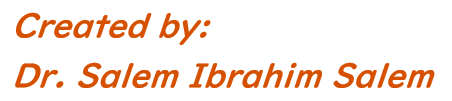

**Student Name(In English)**: Andreiev Maksym

**Student ID**: 2022m666

# **Assignment No. (14)**

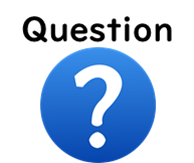

The table shows the monthly precipitation for Kyoto city in 2018 and 2019.

**Write a user-defined function to do the following:**

- Receives the monthly precipitation of one year as an input vector.

- Estimates the mean value of the input vector. 

- Estimates the number of months in which the monthly precipitation is greater than the mean.

- Returns the mean value and the number of months in which the monthly precipitation is greater than the mean as outputs.

**Use the function to estimate the mean precipitation and number of months for 2018 & 2019. (Tip: the data of every year will be the input vector of the function).**

**Display the following message on the secreen for 2018 & 2019 after recieving the data from the function**

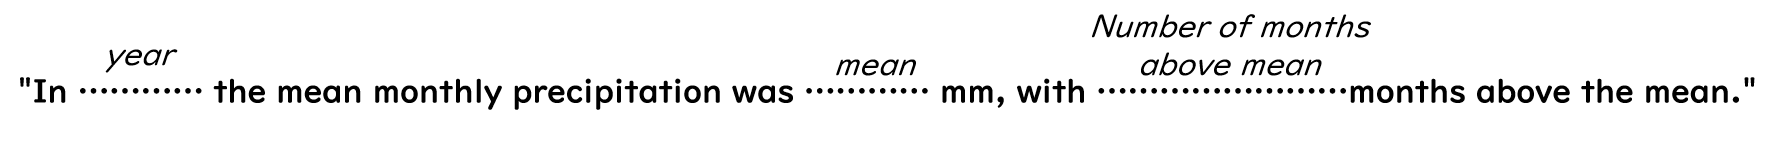

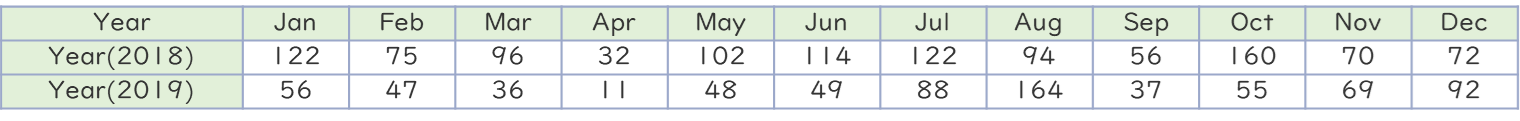

Prec = [122    75    96    32   102   114   122    94    56   160    70    72
         56    47    36    11    48    49    88   164    37    55    69    92 ];

years = [2018, 2019]; % to display the year

for i=1:2
    [year_mean, no_month] = precipitation_data(Prec(i,:));
    string = sprintf('In %d the mean monthly precipitation was %2.2f mm, with %d month above the mean.', ...
        years(i), year_mean, no_month); % formated string to insert data in
    disp(string)
end

In 2018 the mean monthly precipitation was 92.92 mm, with 7 month above the mean.
In 2019 the mean monthly precipitation was 62.67 mm, with 4 month above the mean.


function [mean_, count_] = precipitation_data(year_precipitation)
    mean_ = mean(year_precipitation);
    count_ = numel(year_precipitation(year_precipitation > mean_)); % boolean mask to the array 
end
